**Steps to run:**

- Run script until "Reading Testbench Files"

- Run Vivado "transmit_chain" simulation

- Reformat coe_samples.txt into coe_sample.coe

- Open BRAM gen IP "playback_mem"

- Re-select coe file

- Rerun Vivado simulation

- Run script again

clear; clc; close all; fclose all;

**OFDM Parameters**

% Supported nfft: 128, 256, 512, 1024, 2048, 4096
nfft = 128;
BW_supported = [25000 50000 100000 150000 200000 250000 50000000];
% 50MHz BW only to speed up simulation
BW = BW_supported(7);
M = 16;
cp_len = nfft/4;
cp_len = 0;
ofdm_symbols = 3;
rep = 4;
bypass_read_files = 0;
plot_len = 1:(ofdm_symbols*nfft);
%plot_len = 1:(1*nfft);
scale = 2^5;
if (nfft == 128)
    scale2 = 1.62^5;
elseif (nfft == 256)
    scale2 = 1.74^5;
elseif (nfft == 512)
    scale2 = 1.87^5;
elseif (nfft == 1024)
    scale2 = 2.0^5;
elseif (nfft == 2048)
    scale2 = 2.15^5; % Use for 2048
elseif (nfft == 4096)
    scale2 = 2.30^5; % Use for 4096
end

pilot_index = 1:rep:nfft;
data_index = 1:nfft;
data_index(pilot_index) = [];
scs = BW/nfft;
num_data_bits = length(data_index)*ofdm_symbols;

**Modulate:**

[ofdm_signal,reference_pilot,mod_data,t,t2,freq_data] = ofdm_transmit( ...
    nfft,BW,M,cp_len,ofdm_symbols,[],pilot_index,0,1,scale);

**Writing Testbench Files:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Print modulation info to file
file = fopen('../Xilinx/Vivado/modules/sim/info.txt','wt');
fprintf(file,"%d, %d, %d, %d",ofdm_symbols,BW,nfft,cp_len);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% Print supported bandwidths to file
file = fopen('../Xilinx/Vivado/modules/sim/supported_bandwidths.txt','wt');
fprintf(file,"%d\n",BW_supported);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Print frequency domain IFFT input signal to file
file = fopen('../Xilinx/Vivado/modules/sim/transmit_chain_carriers_in_data.txt','wt');
for i = 1:nfft*ofdm_symbols
    if i == nfft*ofdm_symbols
        fprintf(file,"%d, %d",int16(real(freq_data(i))),int16(imag(freq_data(i))));
    else
        fprintf(file,"%d, %d\n",int16(real(freq_data(i))),int16(imag(freq_data(i))));
    end
end

**Reading Testbench Files:**

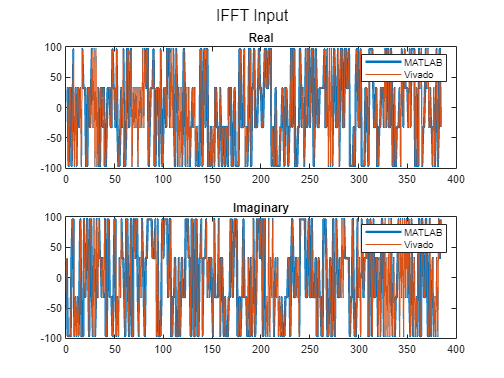

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% IFFT input MATALB vs Vivado
file = fopen('../Xilinx/Vivado/modules/sim/transmit_chain_ifft_sim_in.txt','r');
freq_data_vivado = [];
for i = 1:nfft*ofdm_symbols
    tmp_i = fscanf(file,"%d");
    tmp_q = fscanf(file,",%d");
    tmp_iq = complex(tmp_i, tmp_q);
    freq_data_vivado = [freq_data_vivado tmp_iq];
end
freq_data_plot = reshape(freq_data,[1 nfft*ofdm_symbols]);
if (bypass_read_files) 
    freq_data_vivado = zeros(1,nfft*ofdm_symbols);
end
figure(),subplot(2,1,1),plot(real(freq_data_plot(plot_len)),LineWidth=2)
hold on,plot(real(freq_data_vivado(plot_len))),title('Real')
legend('MATLAB','Vivado'),subplot(2,1,2),plot(imag(freq_data_plot(plot_len)),LineWidth=2)
hold on,plot(imag(freq_data_vivado(plot_len))),title('Imaginary')
legend('MATLAB','Vivado'),sgtitle('IFFT Input')

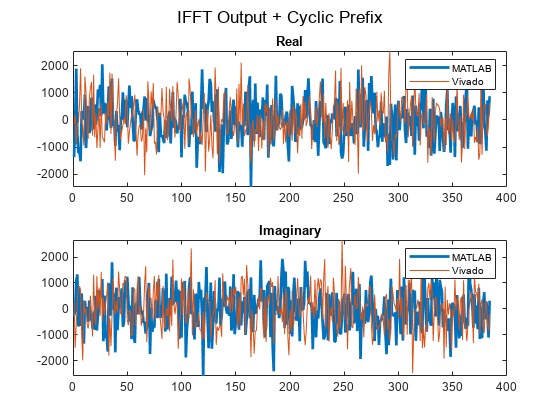

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% IFFT output MATLAB vs Vivado
file = fopen('../Xilinx/Vivado/modules/sim/transmit_chain_ifft_sim_out.txt','r');
time_data_vivado = [];
for i = 1:(nfft+cp_len)*ofdm_symbols
    tmp_i = fscanf(file,"%d");
    tmp_q = fscanf(file,",%d");
    tmp_iq = complex(tmp_i, tmp_q);
    time_data_vivado = [time_data_vivado tmp_iq];
end
ofdm_signal_plot = reshape(scale2*ofdm_signal,[1 ofdm_symbols*(nfft+cp_len)]);
if (bypass_read_files)
    time_data_vivado = zeros(1,ofdm_symbols*(nfft+cp_len));
end
figure(),subplot(2,1,1),plot(scale2*real(ofdm_signal_plot(plot_len)),LineWidth=2),hold on,
plot(real(time_data_vivado(plot_len))),title('Real'),legend('MATLAB','Vivado')
subplot(2,1,2),plot(scale2*imag(ofdm_signal_plot(plot_len)),LineWidth=2),hold on,
plot(imag(time_data_vivado(plot_len))),title('Imaginary'),legend('MATLAB','Vivado')
sgtitle('IFFT Output + Cyclic Prefix')